#### **8) After finding our root limitations, it's time to choose our roots; we choose 8+-8j ; After that find our controller system zeros based on root locations; We use PID controller to make our ess to tend to zero; so we have **

#### **Gc=K (s+z1)(s+z2)/s ; one of our zeros is equal to one of the poles of our transfer function at left; so let's find our poles:**

s = tf('s');
G = 650 / (s^3+250.2*s^2+35.94*s-3515)


G =
 
                650
  --------------------------------
  s^3 + 250.2 s^2 + 35.94 s - 3515
 
Continuous-time transfer function.



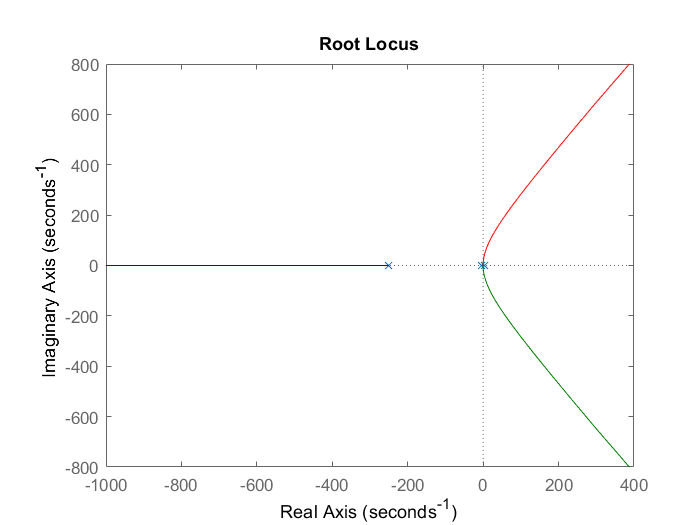

rlocus(G)

#### **As we zoom into them, our poles are: p1=3.65, p2=-3.39, p3=-250.**

**so we choose z1=-3.39.**

**now it's time to calculate our z2 by connecting our poles to one of our chosen pole; I prefer -8+8j; by finding the arctan of their angle with real axis and adding them together + unknown angle, which is for our z2 zero, and equalizing them to an odd coefficient of pi, we can find z2 ( all of the solution is available in our report). so z2=12.63**

**Now we should find K; as we know, |GGc| at one of our chosen poles equals to 1; so:**

s=-8+8j;
G = 650 / (s^3+250.2*s^2+35.94*s-3515);
Gcraw=(3.39+s)*(12.63+s)/(s);
K=1/(abs(G)*abs(Gcraw))

K = 6.2896

#### **9) Step Response & Time Analysis:**

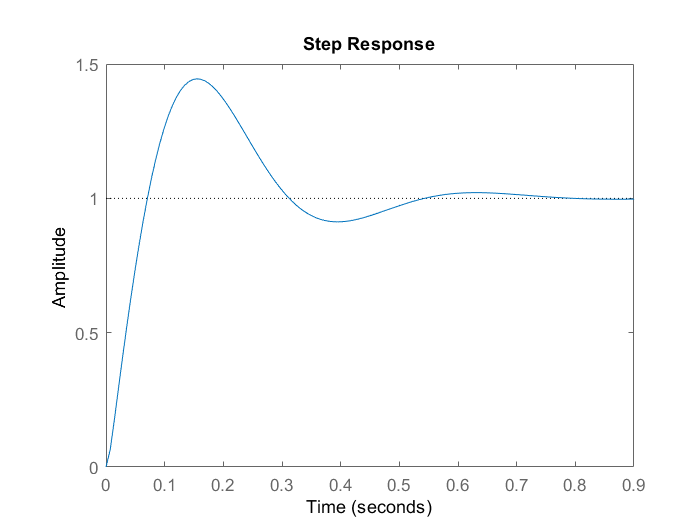

K=6.2896;
s = tf('s');
G = 650 / (s^3+250.2*s^2+35.94*s-3515);
Gc=K*(3.39+s)*(12.63+s)/(s);
H=feedback(G*Gc,1);
step(H)

stepinfo(H)

ans = struct with fields:
        RiseTime: 0.0527
    SettlingTime: 0.6558
     SettlingMin: 0.9124
     SettlingMax: 1.4448
       Overshoot: 44.4813
      Undershoot: 0
            Peak: 1.4448
        PeakTime: 0.1550


#### **10) Root Locus Analysis:**

**As we used PID controller, now we've shifted our roots to the left so our system's became more stable. We've used Routh-Hurwitz table to find the stability factor range in our report.**

K=6.2896;
s = tf('s');
G = 650 / (s^3+250.2*s^2+35.94*s-3515);
Gc=K*(3.39+s)*(12.63+s)/(s);
H=feedback(G*Gc,1);
rlocus(G)

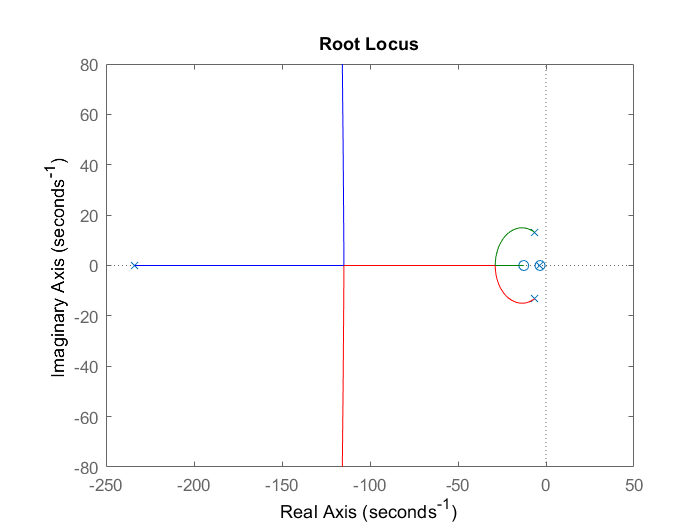

rlocus(H)